clear;clf("reset"); clc;

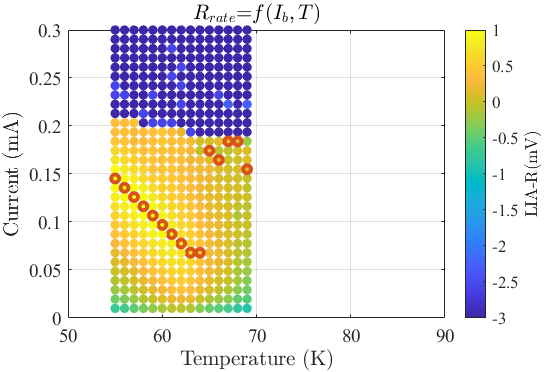

defaultPath = 'I:\WorkSpace\ResearchGroup\RecentWork\YBCO\Bolometer\Data\309test\20230807\';
Path = uigetdir(defaultPath); % Folder path of series test data
File = dir(fullfile(Path,'*.mat')); % Extract all .mat files in the folder
FileNames = {File.name}';
load([Path, '\', FileNames{1}])
len = length(FileNames);
pat = regexpPattern('\d+.\d+K');
RList = [];
ThetaList = [];
BiasList = [];
TempList =[];
for i = 1:len
    if contains(FileNames{i},'LIA')
        load([Path, '\', FileNames{i}])
        Reresult = extract(FileNames{i},pat);
        Temp = str2double(Reresult{1}(1:end-1));
        TList = Temp*ones(length(Bias),1);
        TempList = [TempList;TList];
        RList = [RList;R(:,end)];
        ThetaList = [ThetaList;Theta(:,end)];
        BiasList = [BiasList;Bias'];
    end
end

clf
[pks,locs] = findpeaks(RList,"MinPeakDistance",20);
scatter3(TempList,1e3*BiasList,RList*1e3*2*1.414,50,log10(RList*1e3*2*1.414),"filled");
hold on
scatter3(TempList(locs),1e3*BiasList(locs),RList(locs)*1e3*2*1.414,"LineWidth",3);hold off
view([0 90.0]);box on;xlim([50 90]);caxis([-3 1]);
title('$R_{rate}$=$f(I_b,T)$',"Interpreter","latex");
xlabel('Temperature (K)',"Interpreter","latex");
ylabel('Current (mA)',"Interpreter","latex");
% ylabel('$I_b$',"Interpreter","latex");
set(gca,'FontSize',14,'FontName','Times New Roman');
%set(gca,'YScale','log') % This line for LogScale Current Sweep
c = colorbar; c.Label.String = 'LIA-R(mV)';
c.Label.Interpreter = 'latex';

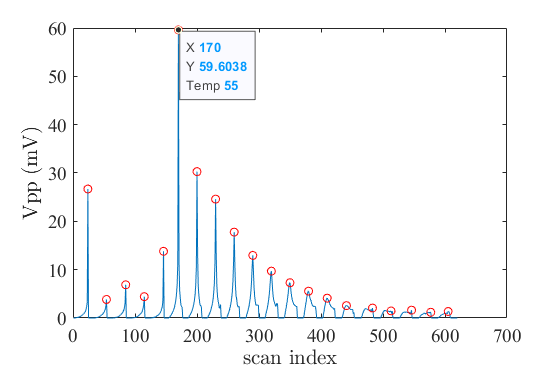



[pks,locs] = findpeaks(RList,"MinPeakDistance",20);
xlist = 1:length(RList);
g = plot(xlist,RList*1e3*2*1.414);hold on
plot(xlist(locs),pks*1e3*2*1.414,'or');hold off
[M, I] = max(pks);
row = dataTipTextRow('Temp',TempList);
g.DataTipTemplate.DataTipRows(end+1) = row;
ax = gca;
chart = ax.Children(2);
datatip(chart,locs(I),pks(I)*1e3*2*1.414);
xlabel('scan index',"Interpreter","latex");
ylabel('Vpp (mV)',"Interpreter","latex");
set(gca,'FontSize',14,'FontName','Times New Roman');

clf;clear;
defaultPath = 'I:\WorkSpace\ResearchGroup\RecentWork\YBCO\Bolometer\Data\309test\20230807\';
Path = uigetdir(defaultPath); % Folder path of series test data
File = dir(fullfile(Path,'*.mat')); % Extract all .mat files in the folder
FileNames = {File.name}';
len = length(FileNames);
for i = 1:len
    if contains(FileNames{i},'LIA')
        %[filename, filepath] = uigetfile('M:\309test\20230807\409-1-15_0.2Hz\LIA\*.mat', '选择文件');
    cd(Path);
    load(fullfile(Path, FileNames{i}));
    % 生成颜色图例
    colorMap = zeros(256, 3);  % 颜色矩阵，每一行表示一个颜色，包括RGB三个通道
    
    % 0-128为白色到红色再到白色的渐变
    colorMap(1:64, 1) = linspace(1, 1, 64);   % 红色通道为1
    colorMap(1:64, 2) = linspace(1, 0, 64);   % 绿色通道从1渐变到0
    colorMap(1:64, 3) = linspace(1, 0, 64);   % 蓝色通道从1渐变到0
    
    colorMap(65:128, 1) = linspace(1, 1, 64);   % 红色通道为1
    colorMap(65:128, 2) = linspace(0, 1, 64);   % 绿色通道从1渐变到0
    colorMap(65:128, 3) = linspace(0, 1, 64);   % 蓝色通道从1渐变到0
    
    % 129-256为白色到蓝色再到白色的渐变
    colorMap(129:192, 1) = linspace(1, 0, 64);   % 红色通道从1渐变到0
    colorMap(129:192, 2) = linspace(1, 0, 64);   % 绿色通道从1渐变到0
    colorMap(129:192, 3) = linspace(1, 1, 64);   % 蓝色通道为1
    
    colorMap(193:256, 1) = linspace(0, 1, 64);   % 红色通道从1渐变到0
    colorMap(193:256, 2) = linspace(0, 1, 64);   % 绿色通道从1渐变到0
    colorMap(193:256, 3) = linspace(1, 1, 64);   % 蓝色通道为1
    
    f1 = figure(1);
    colormap(colorMap);
    TimeList = linspace(0,20,size(R,2));
    [X, Y] = meshgrid(Bias, TimeList);
    f1 = surf(X,Y,Theta');shading interp;box on;
    c = colorbar; c.Label.String = 'Theta (deg.)';
    title('$\theta$=$f(I_b,t)$',"Interpreter","latex");
    set(gca,'FontSize',14,'FontName','Times New Roman');
    xlabel('Bias Current (A)',"Interpreter","latex");
    ylabel('Time (s)',"Interpreter","latex");
    crange = [130-10, 130+10];zlim(crange);caxis(crange);
    view([0 90]);xlim([1e-5 4.0e-4]);ylim([0 20]);
    saveas(f1, ['Theta-',FileNames{i},'.png'],'png');
    
    
    figure(2);
    colormap("default");
    TimeList = linspace(0,20,size(R,2));
    [X, Y] = meshgrid(Bias, TimeList);
    f2 = surf(X,Y,log10(R'));shading interp;box on;
    c = colorbar; c.Label.String = 'log(r(V))';
    title('$r$=$f(I_b,t)$',"Interpreter","latex");
    set(gca,'FontSize',14,'FontName','Times New Roman');
    xlabel('Bias Current (A)',"Interpreter","latex");
    ylabel('Time (s)',"Interpreter","latex");
    zlim([-6 -2]);caxis([-6 -2]);
    view([0 90]);xlim([1e-5 4.0e-4]);ylim([5 20]);
    saveas(f2, ['R-',FileNames{i},'.png'],'png');
    clf;
    end
end

% 唤出文件选择对话框，允许用户选择多个 PNG 图片文件
[fileNames, folderPath] = uigetfile('*.png', '选择图片文件', 'MultiSelect', 'on');

% 检查用户是否选择了文件
if ~isequal(fileNames, 0)
    % 设置每一帧的持续时间（秒）
    frameDuration = 4; % 将此值更改为所需的持续时间
    
    % 创建 VideoWriter 对象
    outputVideo = VideoWriter(fullfile(folderPath, 'output.avi'));
    open(outputVideo);
    
    % 循环读取每个选中的图片并写入视频文件
    for i = 1:length(fileNames)
        % 读取当前图片
        currentImage = imread(fullfile(folderPath, fileNames{i}));
        
        % 写入当前图片到视频文件
        for i = 1:frameDuration
            writeVideo(outputVideo,currentImage);
        end
        
    end
    
    % 关闭 VideoWriter 对象
    close(outputVideo);
    
    disp('视频保存成功。');
else
    disp('未选择图片文件。');
end

视频保存成功。
